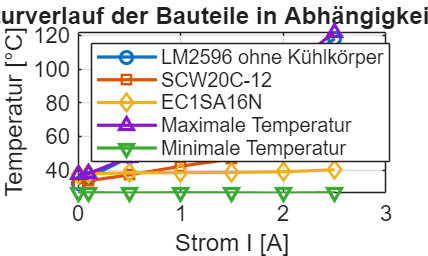

%% Messdaten für Temperaturverlauf der Bauteile

% Strom [A]
I = [0 0.1 0.5 1 1.5 2 2.5];

% Temperaturen [°C]
T_LM2596      = [31.8 35.3 47.8 60.1 75.6 96.6 118];
T_SCW20C12    = [32.1 33.7 37.1 42.3 46.6 54.8 59.1];
T_EC1SA16N    = [37.4 37.9 38.3 38.5 38.6 39.0 40.2];
T_Tmax        = [37.3 37.9 47.6 61.3 77.1 98.1 122];
T_Tmin        = [26.6 26.6 26.4 26.6 26.5 26.4 26.6];

%% Plot
figure;
hold on; grid on; box on;

plot(I, T_LM2596,   '-o', 'LineWidth', 1.6);
plot(I, T_SCW20C12, '-s', 'LineWidth', 1.6);
plot(I, T_EC1SA16N, '-d', 'LineWidth', 1.6);
plot(I, T_Tmax,     '-^', 'LineWidth', 1.6);
plot(I, T_Tmin,     '-v', 'LineWidth', 1.6);

%% Achsen & Beschriftungen
xlabel('Strom I [A]', 'FontSize', 12);
ylabel('Temperatur [°C]', 'FontSize', 12);
title('Temperaturverlauf der Bauteile in Abhängigkeit vom Strom', 'FontSize', 13);

legend( ...
    'LM2596 ohne Kühlkörper', ...
    'SCW20C-12', ...
    'EC1SA16N', ...
    'Maximale Temperatur', ...
    'Minimale Temperatur', ...
    'Location', 'northwest');

%% Wissenschaftliche Darstellung
set(gca, 'FontSize', 11);

Vergleich mit und ohne Kühlkörper

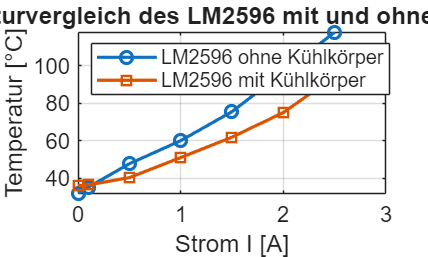

%% Temperaturvergleich LM2596: ohne vs. mit Kühlkörper

% Strom [A]
I = [0 0.1 0.5 1 1.5 2 2.5];

% Temperaturen [°C]
T_ohne = [31.8 35.3 47.8 60.1 75.6 96.6 118];
T_mit  = [36.2 36.5 40.4 51.1 62.0 75.1 94.4];

%% Plot
figure;
hold on; grid on; box on;

plot(I, T_ohne, '-o', 'LineWidth', 1.6);
plot(I, T_mit,  '-s', 'LineWidth', 1.6);

%% Achsen & Beschriftungen
xlabel('Strom I [A]', 'FontSize', 12);
ylabel('Temperatur [°C]', 'FontSize', 12);
title('Temperaturvergleich des LM2596 mit und ohne Kühlkörper', 'FontSize', 13);

legend( ...
    'LM2596 ohne Kühlkörper', ...
    'LM2596 mit Kühlkörper', ...
    'Location', 'northwest');

set(gca, 'FontSize', 11);